# Binary Amplitude Shift Keying (ASK)  

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 

## Variables

clc;
clear;
fc=5;
fs=10*fc;
t=[0:1/fs:20];
A=10;


## Message Signal

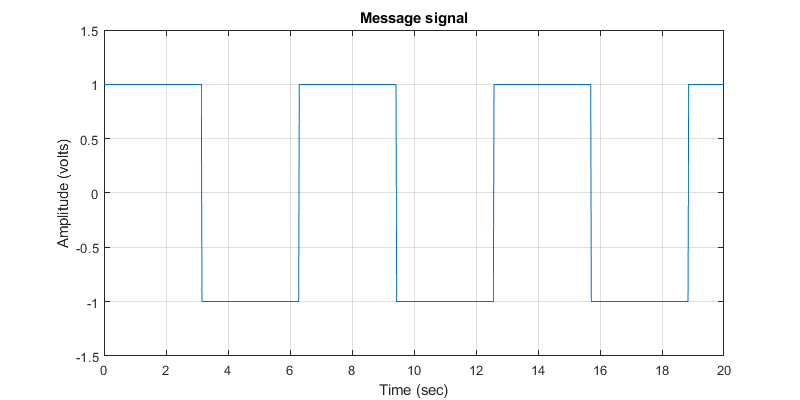

Vm=square(t);
f1=figure;
plot(t,Vm);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Message signal');
ylim([-1.50 1.50])
set(f1,'Position',[0 0 800 400]);
grid on;

## Carrier Signal

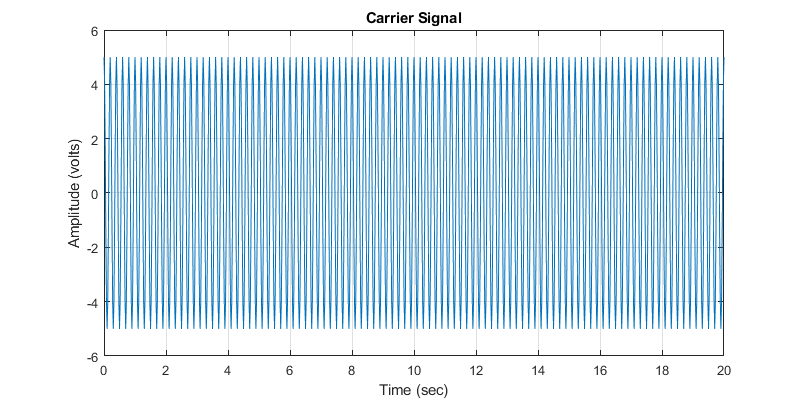

Vc=A/2.*cos(2.*pi.*fc.*t);
plot(t,Vc);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Carrier Signal');
ylim([-6.00 6.00])
set(f1,'Position',[0 0 800 400]);
grid on;

## ASK Signal

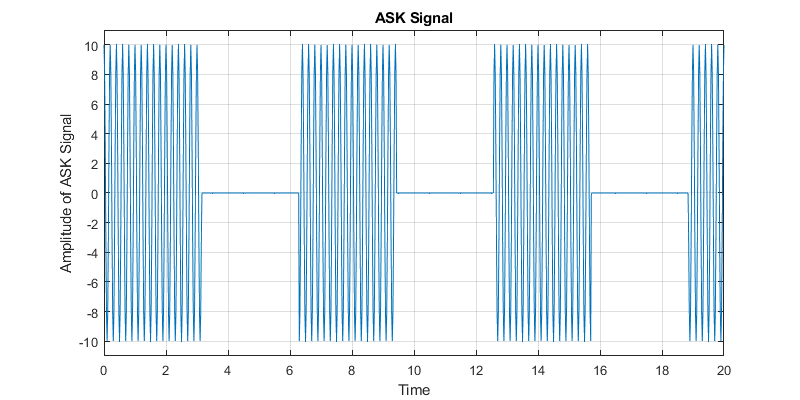

Va=(1+Vm).*(Vc);
plot(t,Va);
xlabel("Time");
ylabel("Amplitude of ASK Signal");
title('ASK Signal');
ylim([-11.00 11.00])
set(f1,'Position',[0 0 800 400]);
grid on;

## Frequency Spectrum of Modulated Signal

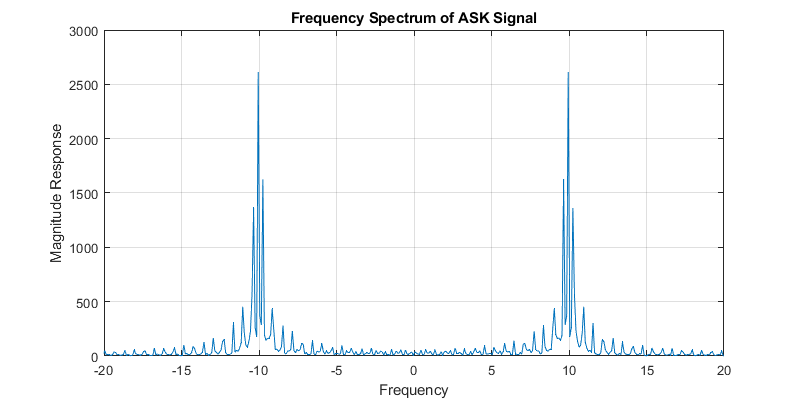

l=length(t);
i=(-l/2:1:l/2-1).*1/10;
plot(i,(fftshift(abs(fft(Va)))));
xlabel("Frequency");
ylabel("Magnitude Response");
title('Frequency Spectrum of ASK Signal');
set(f1,'Position',[0 0 800 400]);
grid on;

xlim([-20 20])
ylim([0 3000])